# EE115 Lab 3 Supplement

# Buddy Ugwumba

- Design the RLC based BPF (i.e., chooose a pair of values for $L$ and $C$) so that $f_0 =100\mathrm{KHz}$ and the $3\mathrm{dB}$ bandwidth is $15\mathrm{KHz}$ 

What I understand:

A band-pass filter allows frequencies within a certain range to pass throuogh, filtering all low and high level frequencies with respect to the that range.

In a parallel RLC circuit the inductor and capacitor work as follows:

The inductor filters low level frequencies; therefore, the higher the inductance the higher the level o f low-level frequencies are filtered out.

The capacitor filteers the high level frequencies; therefore the high ther capacitance, the more high level frequencies are filtereed out. 

We need to find a relationship between the inductor and capacitor so that the peak of our band pass filter is at 100kHz and the frequencies some delta to the left and right of that frequency are filtered out. Specifically, we want to see a half power loss at 7.5kHz. 

Accordin to the following equation: $f=f_0 =\frac{1}{2\pi \sqrt{\mathrm{LC}}}$, the combined value of LC should equal and not exceed 2.53303*10^-12

We will half that value and apply each to LC and change the values of each componenet until we reach our desired filter. 

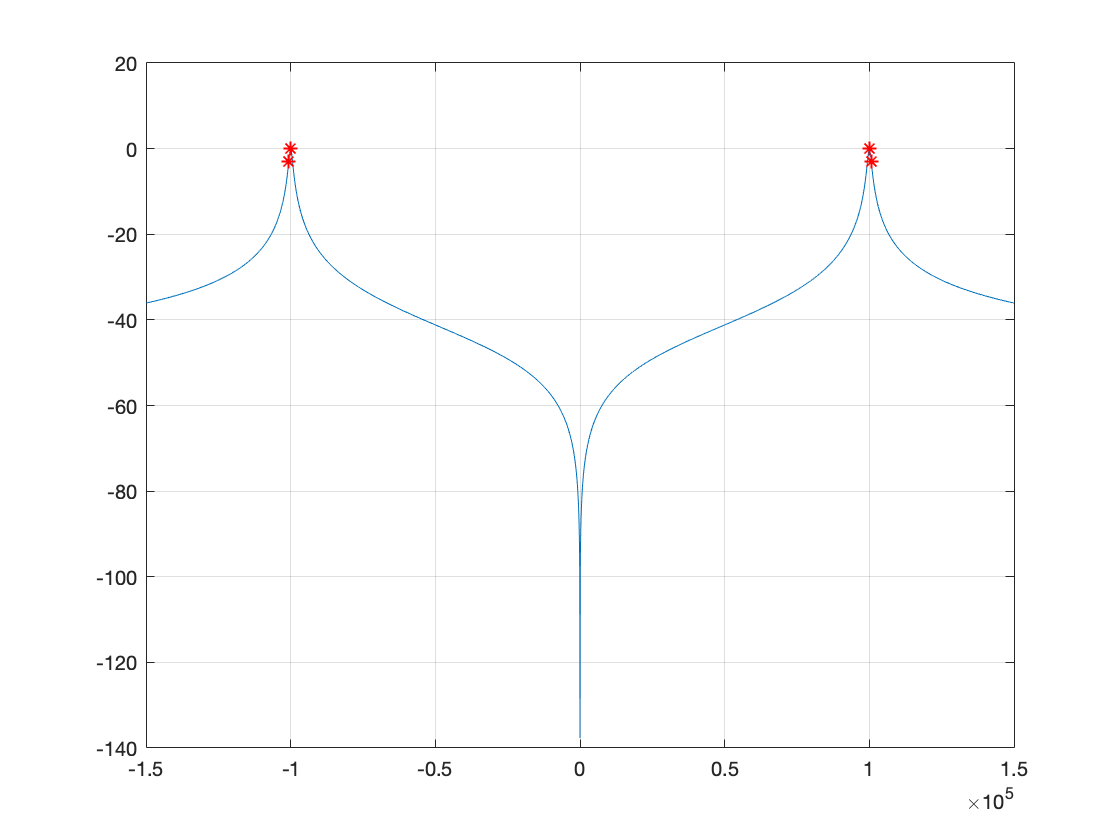

clear all

% Parameters
R = 5000;
R_s = 50;
f_0 = 100*10^3;

C = 24.3*10^-7;
L = (1/(2*pi*f_0))^2*1/C;

% Frequency Range
f = -150*10^3:1:150*10^3;

% Transfer function of the RLC circuit from its input voltage to its output
% voltage 
% Z_delta = 1./((1/R)+(1./(1i*2*pi*(f+7.5*10^3)*L))+(1i*2*pi*(f+7.5*10^3)*C));
Z = 1./((1/R)+(1./(1i*2*pi*f*L))+(1i*2*pi*f*C));
H_omega = Z./(R_s + Z);
% H_omega_delta = Z_delta./(R_s + Z_delta);

%The 3dB bandwidth of |H(j2pif)|
H_3 = 20*log10(abs(H_omega));

figure
plot(f,(H_3));
hold on 
grid on
plot(-1e+05, 0.099, 'r*', -1.007e+05,-3.033, 'r*');
hold on
plot(1e+05, 0.099, 'r*', 1.007e+05,-3.033, 'r*');

The following values for L and C meet the requirements for a bandpass filter to drop 3dB: the inductor L should be 1.0424e-6, and the capacitor C should be 2.43e-6. When multiplied together, these values equal 2.53301e-12; the value calculated in the beginning for what L and C should be when multiplied together based on the response frequency. At the response frequency, the power level is 0.099. 7.5kHz to the right or left of the positive and negative quadrants of the x-axis, the power level drops by -3dB. The data cursor tool helped make these measurements. What was frustrating was that no matter how many times I zoomed in, I could not get the point exact enough so that the data point remained on the curve regardless of the zoom intensity. At some point, these data points would no longer appear directly on the graph. 

2. Design the RLC based BPF (i.e., chooose a pair of values for $L$ and $C$) so that $f_0 =100\mathrm{KHz}$ and the $3\mathrm{dB}$ bandwidth is $15\mathrm{KHz}$ 

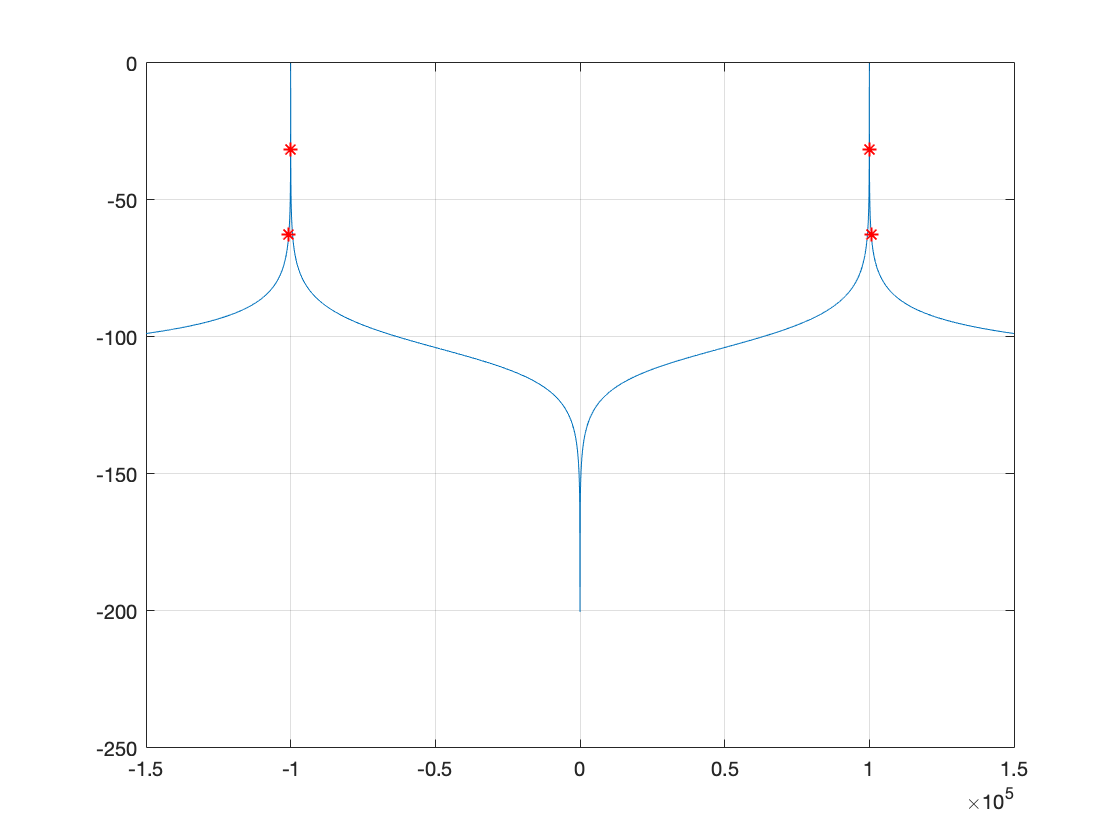

clear all

% Parameters
R = 5000;
R_s = 50;
f_0 = 100*10^3;

C = 3.3*10^-3;
L = (1/(2*pi*f_0))^2*1/C;

% Frequency Range
f = -150*10^3:1:150*10^3;

% Transfer function of the RLC circuit from its input voltage to its output
% voltage 
% Z_delta = 1./((1/R)+(1./(1i*2*pi*(f+7.5*10^3)*L))+(1i*2*pi*(f+7.5*10^3)*C));
Z = 1./((1/R)+(1./(1i*2*pi*f*L))+(1i*2*pi*f*C));
H_omega = Z./(R_s + Z);
% H_omega_delta = Z_delta./(R_s + Z_delta);

%The 3dB bandwidth of |H(j2pif)|
H_3 = 20*log10(abs(H_omega));

figure
plot(f,(H_3));
hold on 
grid on
plot(-1e+05, -31.44, 'r*', -1.007e+05,-62.64, 'r*');
hold on
plot(1e+05, -31.44, 'r*', 1.007e+05,-62.64, 'r*');

The following values for L and C meet the requirements for a bandpass filter to drop 30dB: L should be 7.6758e-11, and C should be 3.3e-2. When multiplied together, these values equal 2.53301e-12; the value calculated in the beginning for what L and C should be when multiplied together based on the response frequency. At the response frequency, the power level is -31.44. 7.5kHz to the right or left of the positive and negative quadrants of the x-axis, the power level drops by -30dB. The data cursor tool helped make these measurements. What was frustrating was that no matter how many times I zoomed in, I could not get the point exact enough so that the data point remained on the curve regardless of the zoom intensity. At some point, these data points would no longer appear directly on the graph.